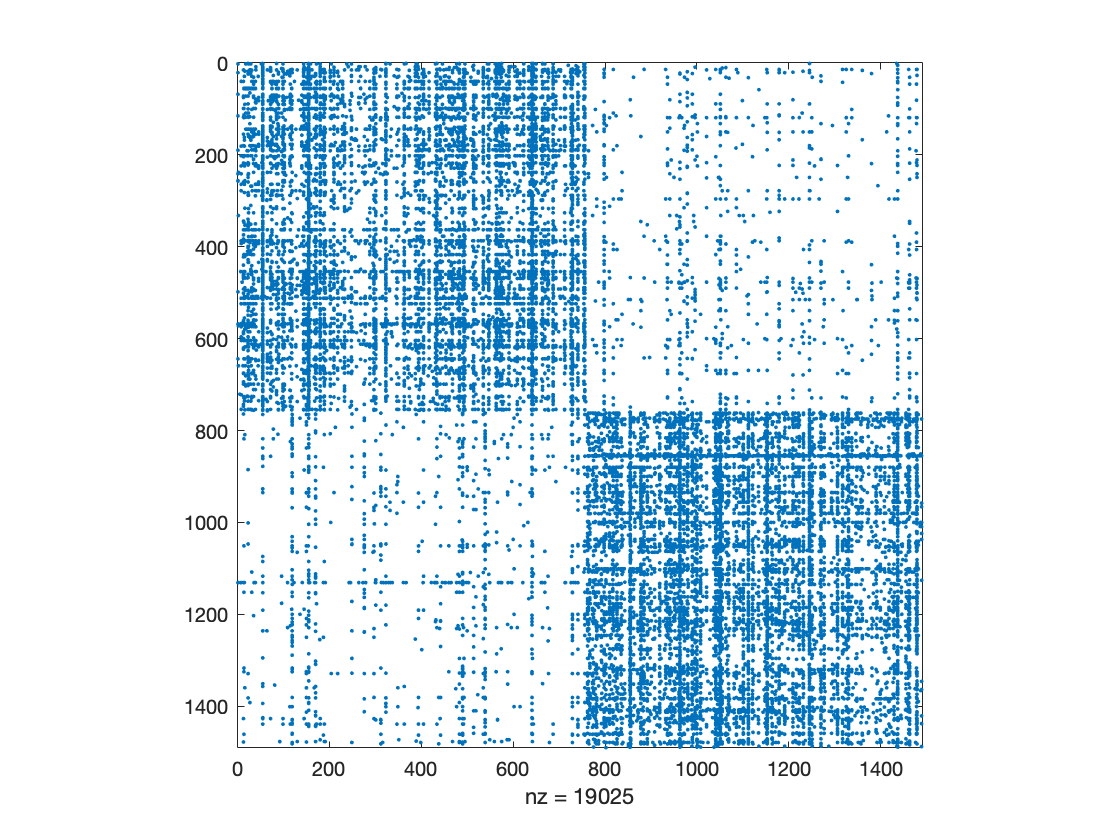

clear
%load("spectralGraphPartitioning-karate.mat");
load("spectraGraphPartitioning-polblogs.mat");
% load("spectralGraphPartitioning_circle_3.mat");
% load("spectralGraphPartitioning_circle_4.mat");

A = Problem.A;
spy(A);

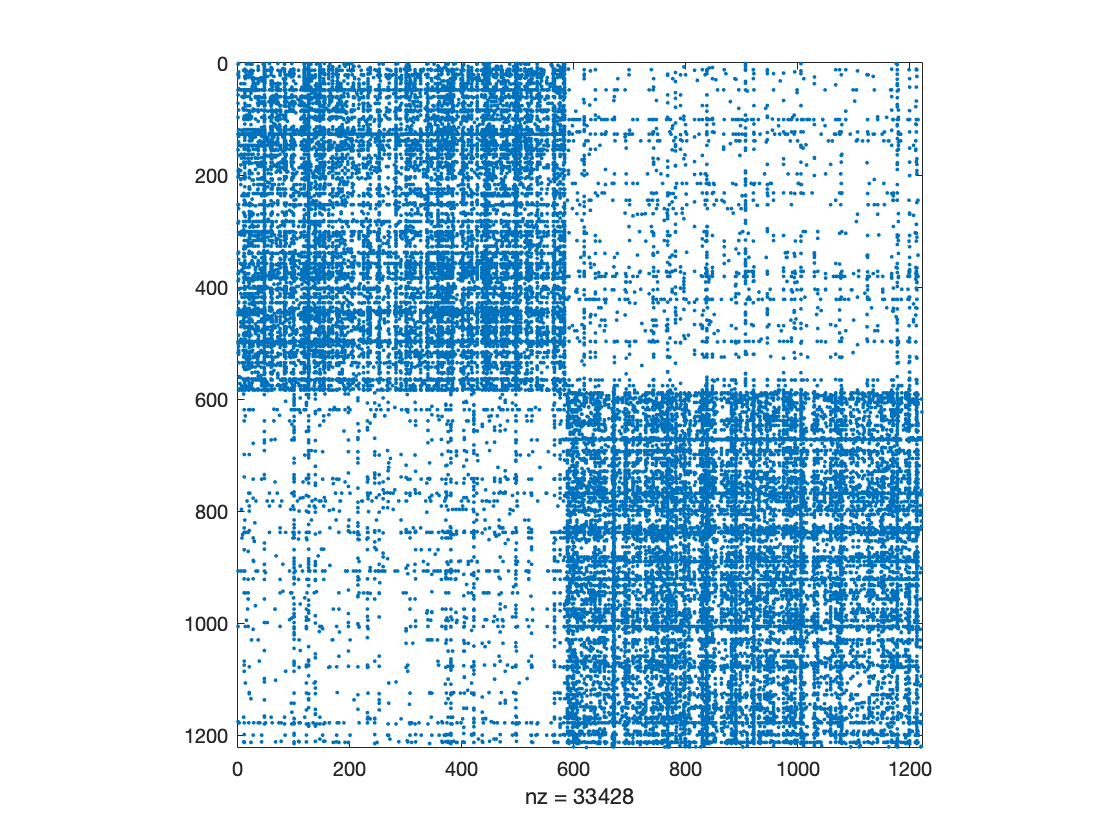


An=normalizeA(A);


spy(An)

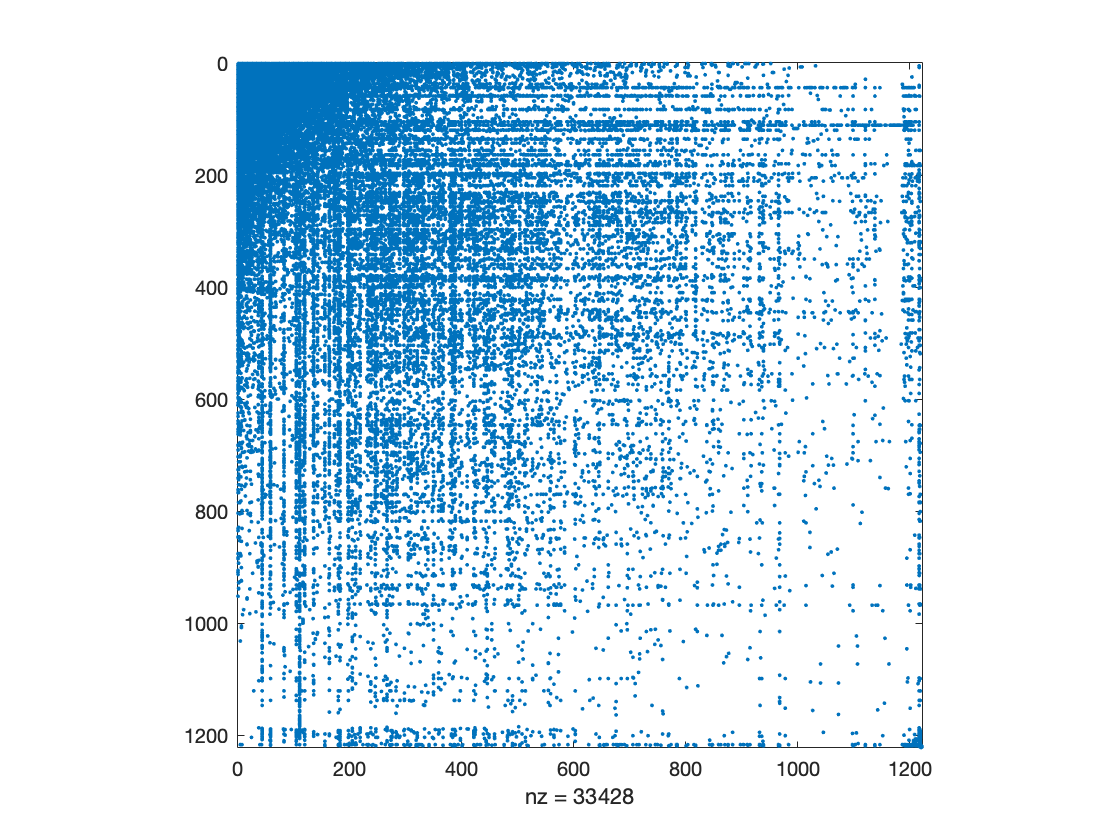


[Ln,d]=GetLaplacian(An);
Ln=normalizeL(Ln);
Fiedler=GetFiedler(Ln);
[Ap,P,p]=PermuteA(Fiedler,An);

spy(Ap);

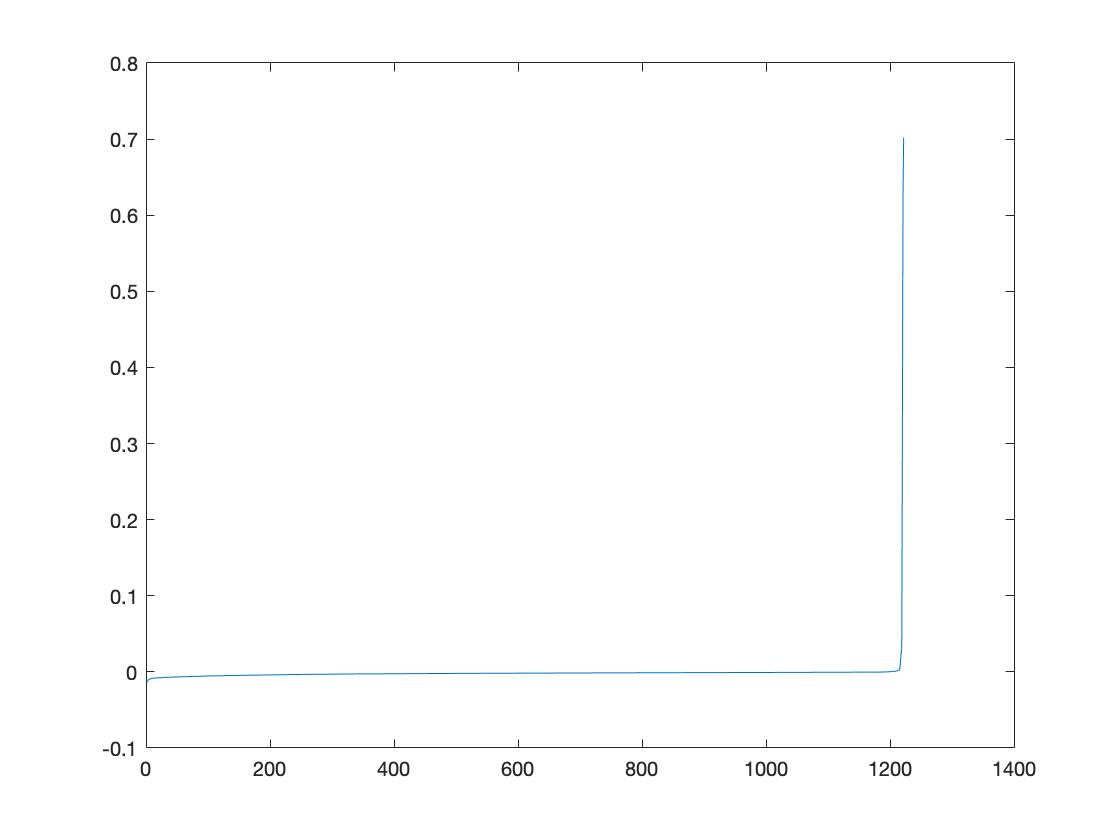


plot(Fiedler(p),'-');

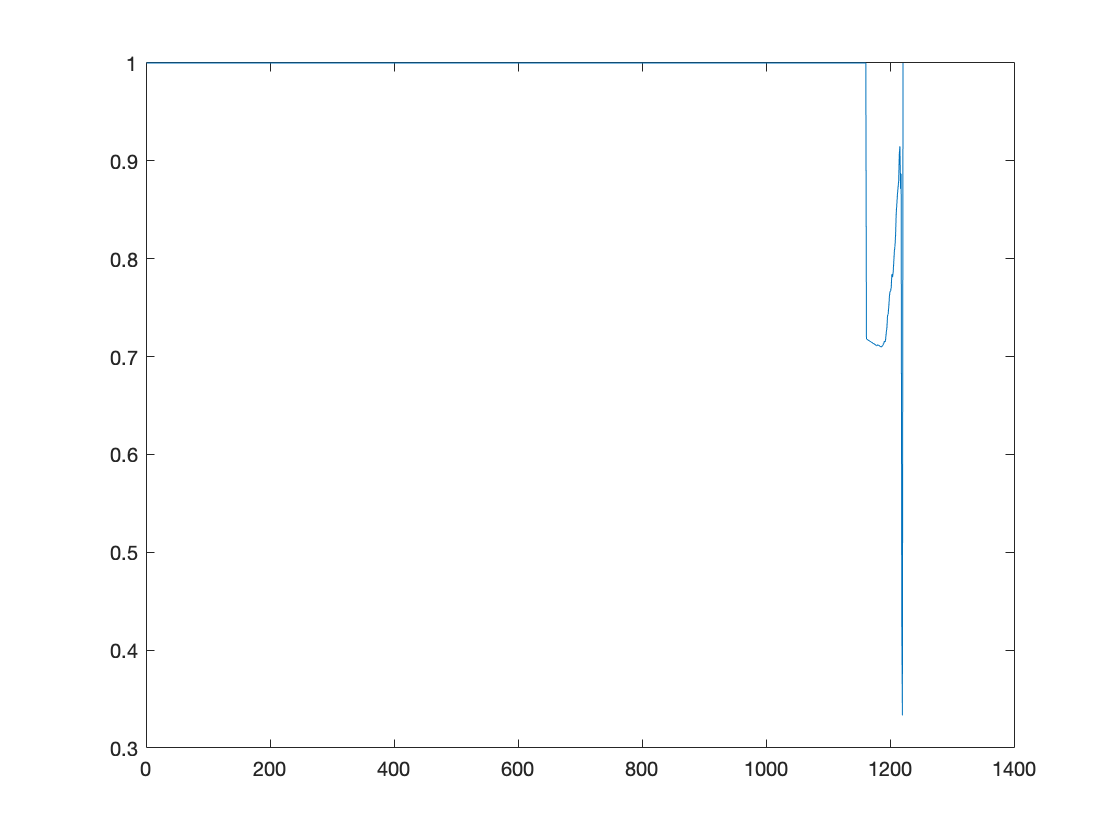



[f1,f2]=splitFiedler(Fiedler,0);

n=sum(f2);

dp = permuted(P,d);

[cond,minInd]=conductance(Ap,dp,n);

plot(cond(:,1),'-');


n=minInd

n = 1220

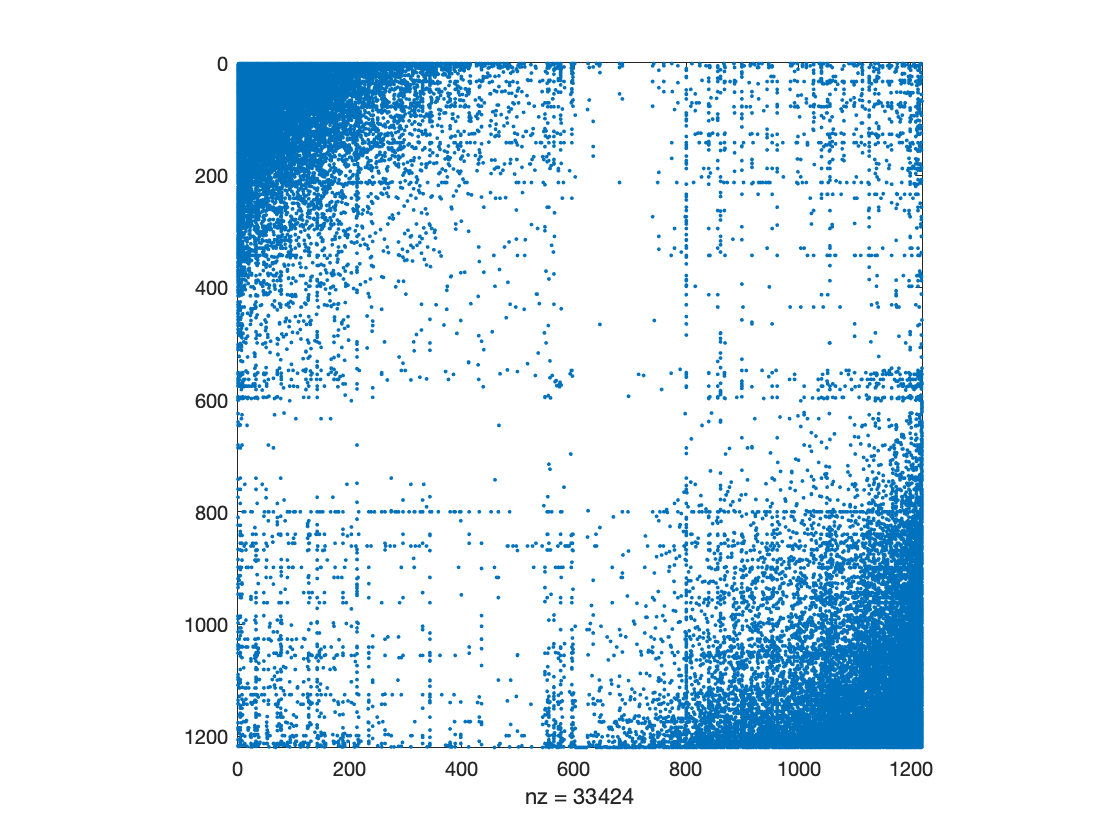


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Ap2=Ap(1:n,1:n);

[Ln1,d1]=GetLaplacian(Ap2);
Ln1=normalizeL(Ln1);
Fiedler1=GetFiedler(Ln1);
[Ap1,P1,p1]=PermuteA(Fiedler1,Ap2);

spy(Ap1);

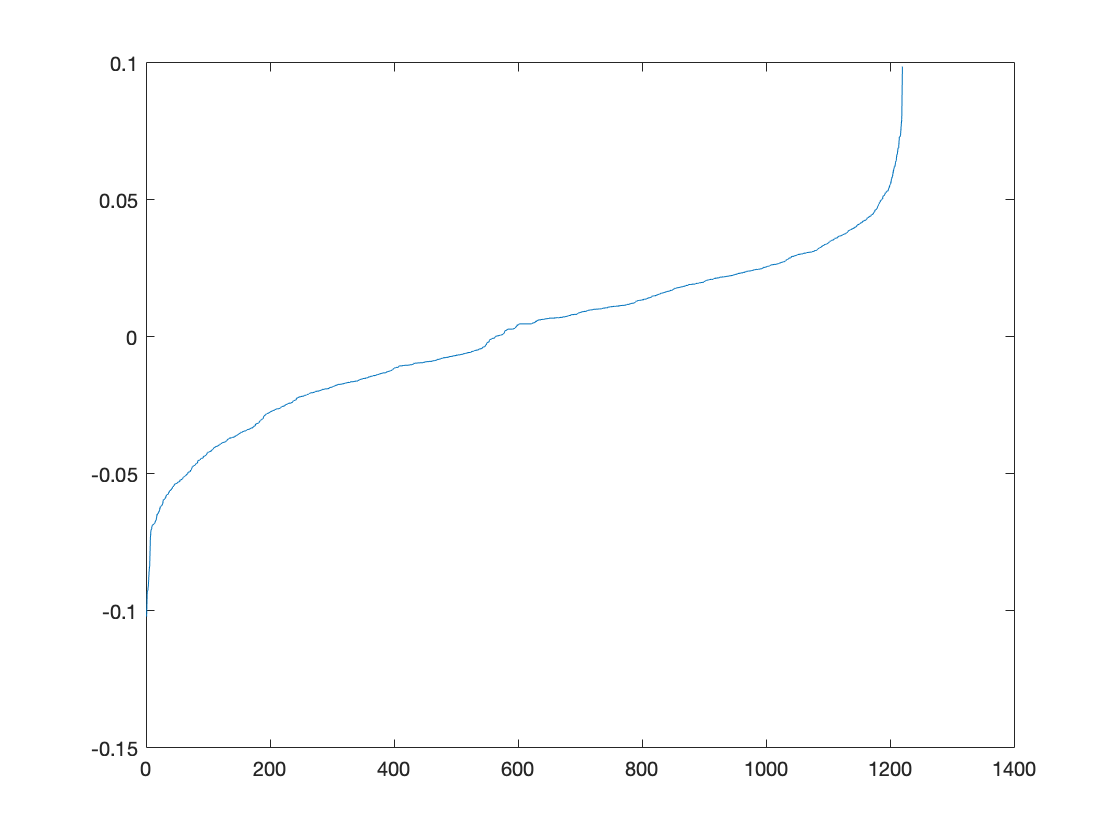


plot(Fiedler1(p1),'-');

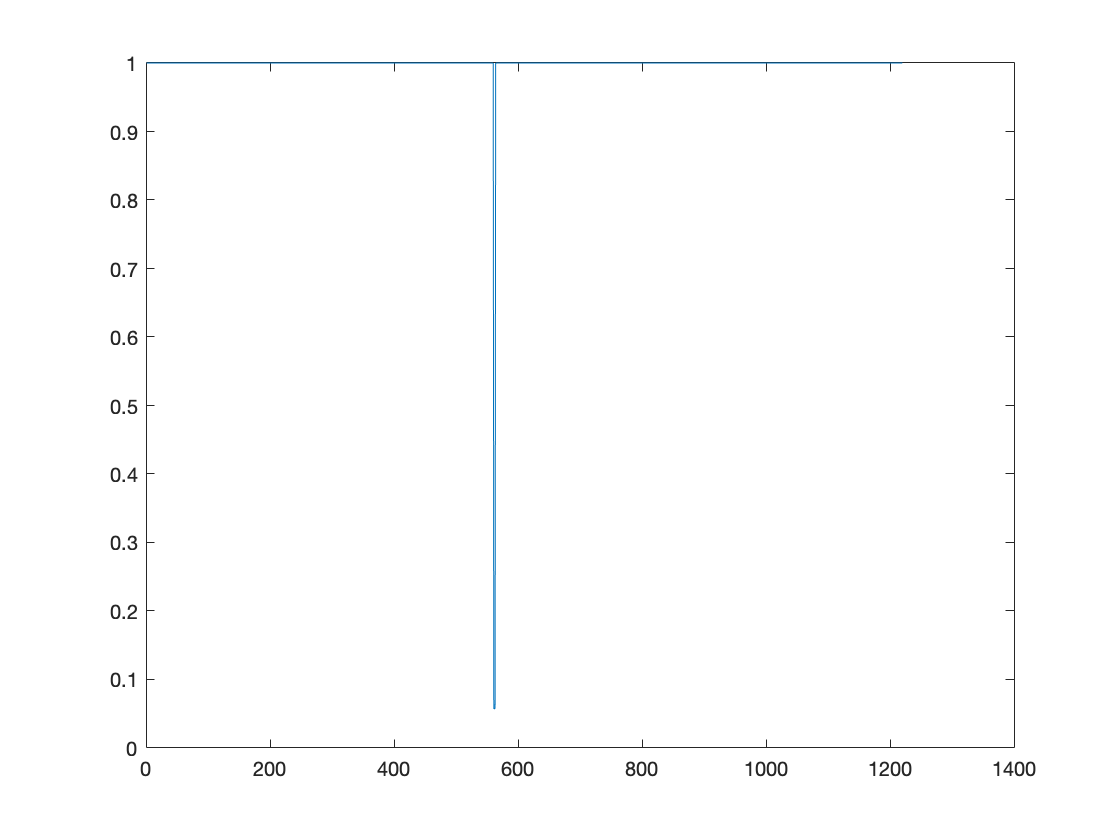


dp1 = permuted(P1,d1);

[f1,f2]=splitFiedler(Fiedler1,0);


n=sum(f2);

[cond1,minInd1]=conductance(Ap1,dp1,n);

plot(cond1(:,1),'-');


n=minInd1

n = 562